close("all"); clear; clc;
yalmip("clear");

s = sqrt(2/3);

G = [
    1,1,0;
    1,-1,0;
    1,0,1;
    1,0,-1;
    0,1,1;
    0,1,-1;
    s,s,s;
    s,s,-s;
    s,-s,s;
    s,-s,-s;
    ];

tic;
Pa = verticesBruteForce(G);
toc;

Elapsed time is 5.559625 seconds.


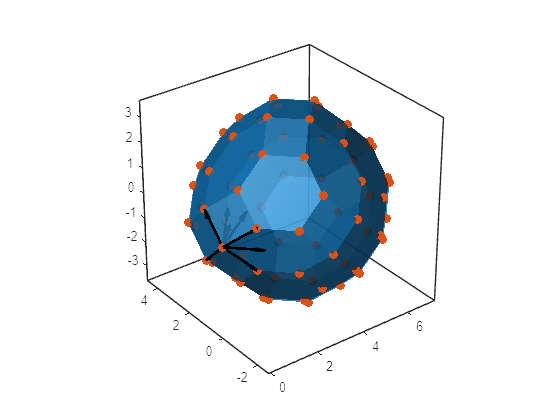

fig = plot(G,Pa);

tic;
Pb = verticesLayered(G);
toc;

Elapsed time is 2.003725 seconds.


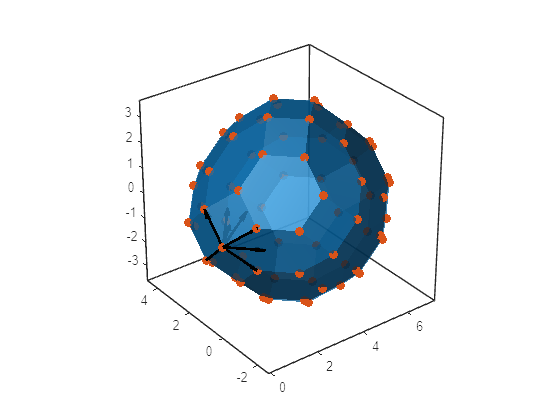

fig = plot(G,Pb);

function plotGenerators(axe,G)
    fg = @(g)quiver3(axe,0,0,0,g(1),g(2),g(3),"off", ...
        "Color",'k', ...
        'LineWidth',2, ...
        'MaxHeadSize',1);
    cellfun(fg,num2cell(G,2),"uniform",0);
end

function plotVertices(axe,P)
    scatter3(axe,P(:,1),P(:,2),P(:,3),"filled", ...
        "MarkerFaceColor","#D95319", ...
        "MarkerEdgeColor","#D95319");
end

function plotZonohedron(axe,P)
    P = unique(P,"rows");
    dT = delaunayTriangulation(P);
    [Tfb,Xfb] = freeBoundary(dT);
    TR = triangulation(Tfb,Xfb);
    trisurf(TR, ...
        "Parent",axe, ...
        "FaceColor","#0072BD", ...
        "EdgeColor","none", ...
        "FaceAlpha",0.75);
end

function fig = plot(G,P)
    fig = figure();
    axe = axes(fig);
    view(axe,3);
    hold(axe,"on");
    plotGenerators(axe,G);
    plotZonohedron(axe,P);
    plotVertices(axe,P);
    hold(axe,"off");
    box(axe,"on");
    axis(axe,"equal");
    light(axe,"Position",[-100,0,100]);
    camproj(axe,"perspective");
end